# cool epic title here 

*Authors:* Anjum Khalifa, Andrew Aburustum

## Generative AI (genAI) Usage Statement

I (Anjum Khalifa) did not use GenAI while completing this assignment.

I (Andrew Aburustum) did not use GenAI while completing this assignment other than formatting GitHub.

## 1. Modeling Question

How fast do a group of countries need to close its borders to stop the spread of a disease, after transmission has been identified, in order to effectively reduce the rate of spread of disease?

When an epidemic is identified, countries closing borders and prohibiting international travel is typically used as a preventative measure, to reduce the likelihood of a virus managing to escape containment in one country and become a global pandemic. This has been studied and modeled extensively with COVID-19, determining how effective border closures were on containing the virus and what could have happened with open borders. However, most of these studies focus on the presence of the border, and not on the speed at which it is established. 

We were curious about how a disease might spread across countries if those countries close their borders immediately after a disease is identified within its borders, or if they wait to establish a border until the disease has spread further. Unfortunately, we were uncertain of how this might be modeled, and what factors (ocean vs. land border, country size, prior policies, social connection within countries, etc.) would be necessary in our model. To answer this question, we conducted background research on this topic and synthesized our findings.

Specificity: Our question is a specific question. We are not seeking to understand the general behavior of restricted travel on a global pandemic, but instead exactly how fast one must be implemented to reduce the spread of such a pandemic. 

Action: Our question is a rhetorical question. While our results may indicate that policy must be skewed one way or another to control the international spread of a virus, we are not taking direct action based on our results, and instead seeking to inform decisions others may make in the future.

## 2. Literature Search

Synthesis matrix: [*https://docs.google.com/spreadsheets/d/1xcnw-RDwNBq6Txi01jzwjk31aJafs17oE7vinwlC54A/edit?usp=sharing*](https://docs.google.com/spreadsheets/d/1xcnw-RDwNBq6Txi01jzwjk31aJafs17oE7vinwlC54A/edit?usp=sharing) 

To research our modeling question and identify any previous work done on the topic, we analyzed three articles related to border closures during the COVID-19 pandemic and learned the following: Kang et al. (2020) used a synthetic control method to analyze the effect of closed borders on six countries exposed to the COVID-19 virus, and found that for each country, their simulated number of cases rose dramatically when borders remained open. Hossain et al. (2020) had very similar results, but additionally showed that border controls were less effective when facing a more contagious virus. Poirier et al. (2023), however, analyzed the effects of targeted border restrictions (those that ban travel to and from specific countries, as opposed to all countries) to those of total border restrictions, and found that the targeted border closures did not lead to the reduced spread of COVID-19, while total closures did.

While all of these articles proved that border closures are effective tools for preventing the spread of a disease, and that the stricter and more restrictive they are, the more effective they are, none of them answered our question about how quick they must be implemented to reduce the rate of infection by a sizable amount. We did, however, gain a good foundation on what is permissible to exclude from our model while still being able to use it, and using that information, we are now able to build a model capable of answering our modeling question.

## 3. Natural World

*Border closures have been studies a lot since COVID-19 and research shows that it helps to close borders as fast as possible. *Kang et al. (2020) used a  control method on six countries and found that border shutdowns reduced the spread as opposed to what would have happened with open borders. Poirier et al. (2023) compared closures, which ban non-essential entry from all countries, to targeted closures, which ban entry from specific countries. They found that targeted closures globally by February 5, 2020 did not slow global transmission, while total closures implemented by March 19, 2020 did produce a statistically significant reduction. Hossain et al. (2020) used a model with quarantine, and found that control measures could gain an extra 32.5 to 44.0 days in arrival time under a low R_0 of 1.4, but only about 10 extra days if R_0 was higher at 2.92. These studies show that closing borders helps, that total closures work better than targeted ones, and that closures help less when a disease spreads faster.

None of these studies tells us how fast borders have to close. The closest result is from Poirier et al. (2023), who found that early closure was associated with more beneficial effects, while late had worse outcomes. That shows earlier is better, but it doesn't give a specific time. These studies also include details we assumed we don’t need for our question like real travel data and quarantine times (Hossain et al., 2020), real  data from many countries (Kang et al., 2020; Poirier et al., 2023), and targeted closures (Poirier et al., 2023). They matter in the real world, but they would add many parameters that we can’t measure, and they aren't needed to see how closure timing changes the outcome. 

We kept what the studies agree on that closing borders reduces spread, so our model has a border closure rule. Disease speed matters, so our model has infection and recovery rates. Infections can cross borders, so our model detects the first cross-border infection. We only model total closures, since those were the type that worked in Poirier et al. (2023). Our model then tests many closure delays to find the longest one that is still effective.

## 4. Model: Representation & Assumptions

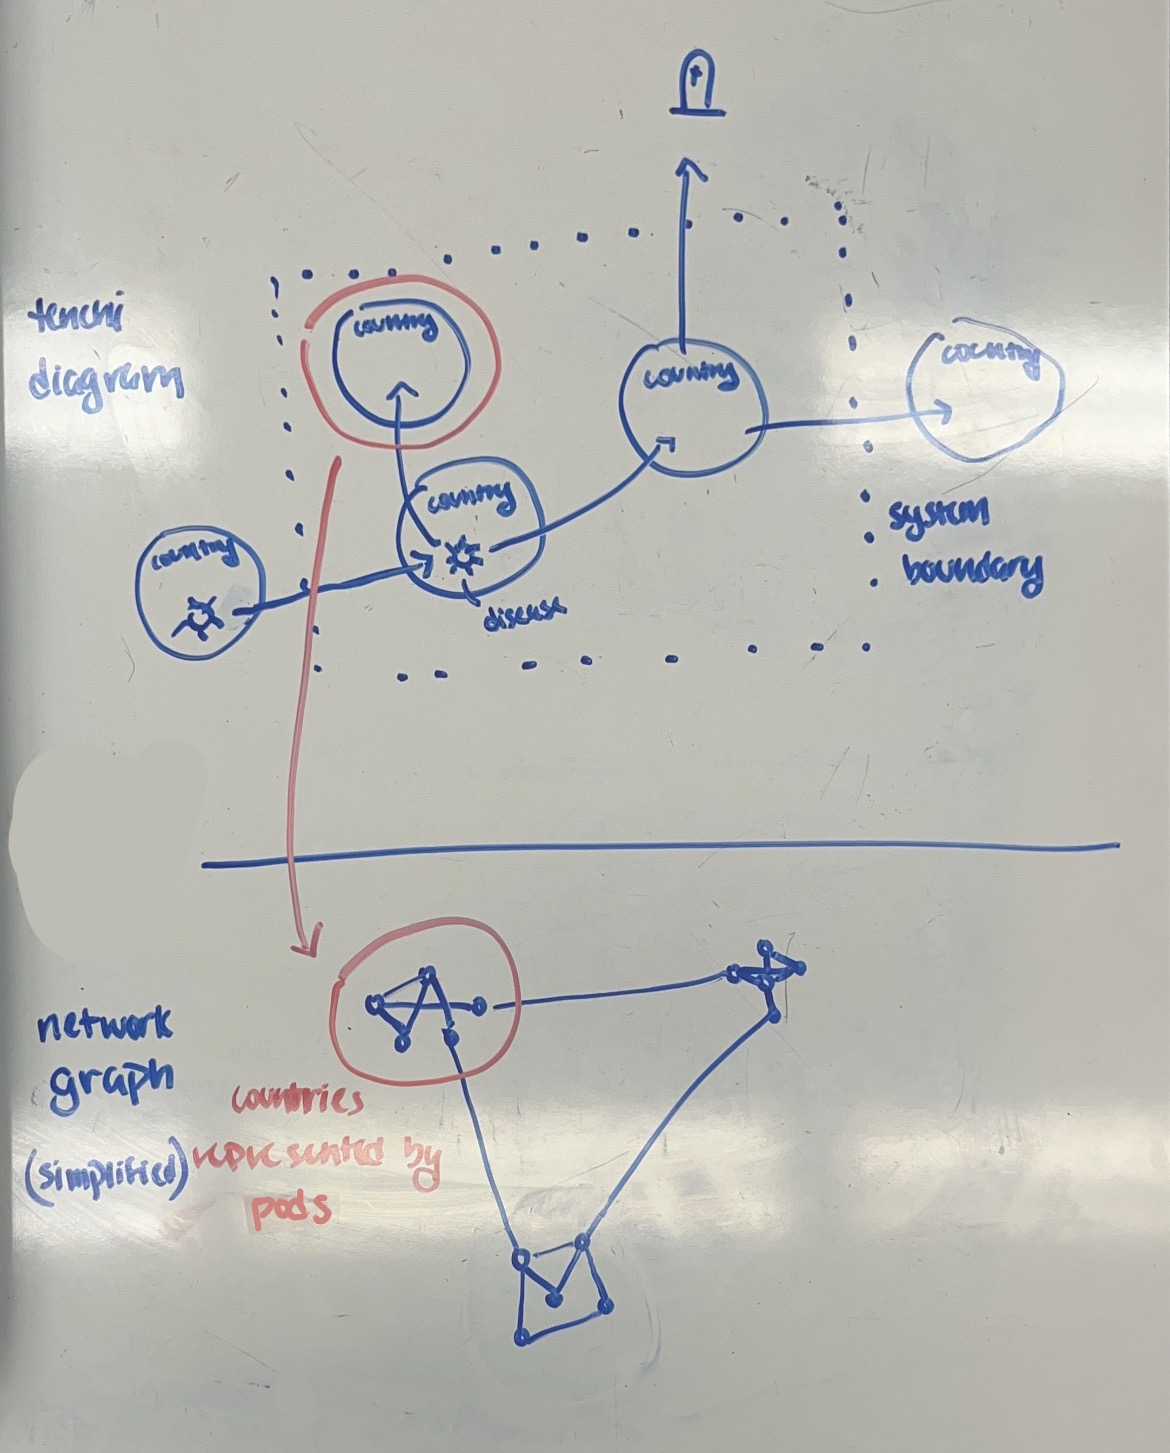

*Fig. 1. Our tenchi diagram and (simplified) network graph. *

Within our system boundary, we include some countries with connections between them, through which a disease can be transmitted. Outside of our system diagram, we have changes in population, as well as other countries. In our network graph, we simplify the natural world into pods representing countries.

Our question is how long after the first cross-border infection is detected countries can wait before closing their borders and still effectively reduce the spread. We define “effectively reduce” as cutting the peak number of infected people at one time to half of what it would be if borders never closed.

In our representation of the natural world, we only care about countries as groups of people, limited contact between countries but greater contact across countries, the rate at which people are infected, recover, and die, and how fast a border closes after an infection is detected. However, it is impossible to include everything in our model, due to complexity constraints and limited processing power. Furthermore, we know that in the physical world, additional factors such as differences in social interactions and dynamics within and between countries, natural immunity and vulnerability to illnesses, vaccines and other preventative behavior, and others contribute to the spread of disease. 

Fortunately, we have learned from our literature search that our model does not need to include all of these topics in order for our model to be usable. Additionally, we have simplified countries into a "leaky pod" model, where every individual in one pod has a 10% chance of being connected with another member of that pod, and an 0.5% chance of being connected with an individual in another pod. Using random chance like this allows us to model more realistic domestic and international social dynamics.

Each country is a pod of 100 agents. Inside a pod, agents are connected often. Between pods, they are connected rarely, so the borders are “leaky.” We built this by going through every pair of agents and connecting them with probability `p_in` if they’re in the same country and `p_out` if they’re not, with `p_out` much smaller than `p_in`.

Our disease follows a typical SIR model, where susceptible individuals connected to infected individuals become infected according to our infection rate, and recover independently according to a recovery rate. We chose to model our disease after COVID-19, and using values discussed by AlQadi et al., we can give our model an infection rate of 0.5, and a recovery rate of 0.13.

clear; clc; close all;

## Parameters

nCountries = 4; % We define 4 countries in our model
nPer = 40; % with 100 individuals in each country
N = nCountries * nPer; % and 4 * 100 = 400 individuals total

p_in  = 0.1;   % chance of connection of people within countries
p_out = 0.005; % chance of connection of people between countries
infection_rate = 0.5; % infection rate of COVID
recovery_rate  = 0.13; % recovery rate of COVID
T = 200; 
nTrials = 500; 
delays = [0:1:20, Inf];   % inf is never close borders

## Simulation

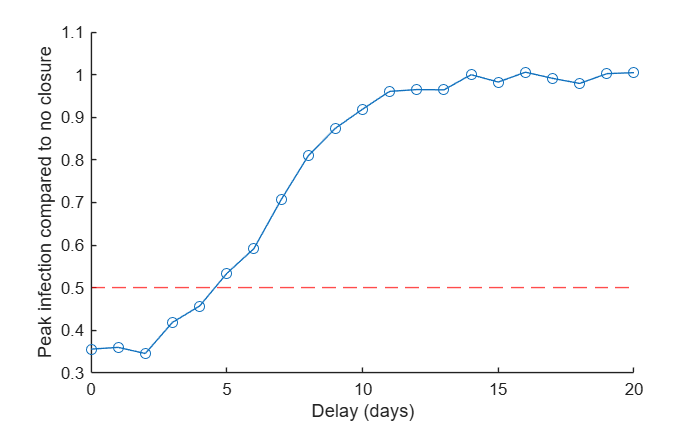

% label each person with their country 
country = zeros(N, 1);
for c = 1:nCountries
    country((c-1)*nPer + 1 : c*nPer) = c;
end

% build the friendship map, based on each individual's country
M = zeros(N, N);
for i = 1:N
    for j = i+1:N
        if country(i) == country(j) % checking if they are in the same country
            p = p_in;
        else
            p = p_out;
        end
        if rand < p
            M(i,j) = 1;
            M(j,i) = 1;
        end
    end
end

% adding one infected person
Iv0 = zeros(N, 1);
Iv0(1) = 1;

% simulating our model
results = zeros(length(delays), nTrials);
for d = 1:length(delays)
    for k = 1:nTrials
        [Sh, Ih, Rh] = simulate_absir(M, Iv0, T, infection_rate, recovery_rate, country, delays(d));
        results(d, k) = max(sum(Ih, 1));
    end
end

avg = mean(results, 2);
ratio = avg / avg(end);

figure; hold on;
plot(delays(1:end-1), ratio(1:end-1), '-o')
xlabel("Delay (days)");
ylabel("Peak infection compared to no closure");
yline(0.5, '--r')
hold off;

*Fig 2. A plot of the results of our model. The x axis is the length of the delay before borders are closed, and the y axis are the ratios between the peak infection for that delay, and the peak infection for no delay (ie. borders are never closed). We include the line y=0.5 as a baseline to observe how long a delay can be before it is no longer effective (peak infection rate is no longer reduced to half.)*

% find the longest delay that cuts peak infected individuals in half
threshold = -1;
for d = 1:length(delays)-1
    if ratio(d) <= 0.5
        threshold = delays(d);
    end
end
disp(threshold)

     4



We find that borders can remain open for up to **[todo: run full simulation and put a number here]** days before failing to effectively reduce the spread of disease.

## 5. Verification & Validation

A model of border closure should give fewer infections when borders close than when they never close, and fewer when they close sooner rather than later. This isn’t immediately obvious, because the model is random, so any one run could go either way. So we averaged over 500 runs for each delay and used `assert` to check both facts. The model passed, so closing at detection gives fewer infections than never closing, and closing right away gives fewer than closing after 20 days.

assert(avg(1) < avg(end))
assert(avg(1) < avg(end-1))

The articles say three things we can compare to our model. Kang et al. (2020) found that cases rose  when borders stayed open. In our model, never closing gave the most infections, which agrees with that. Poirier et al. (2023) found that early closure was associated with better outcomes and late closure with worse ones. Hossain et al. (2020) found that border controls helped much less when the disease spread faster. When we raised the infection rate from 0.4 to 0.6, the threshold delay went from **[todo: rerun and add actual numbers here]**, which matches.

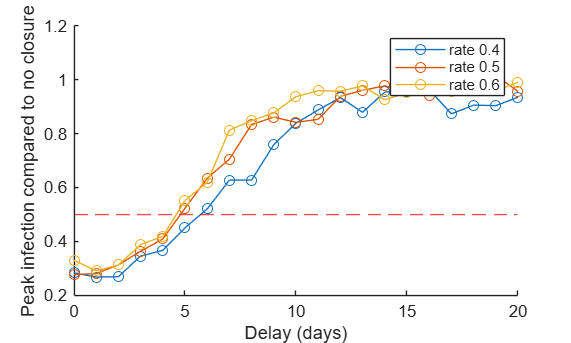

rates = [0.4 0.5 0.6];
nTrialsV = 100;
thresholds = zeros(1, length(rates));
baselines = zeros(1, length(rates));

figure
hold on
for r = 1:length(rates)
    resultsV = zeros(length(delays), nTrialsV);
    for d = 1:length(delays)
        for k = 1:nTrialsV
            [Sh, Ih, Rh] = simulate_absir(M, Iv0, T, rates(r), recovery_rate, country, delays(d));
            resultsV(d, k) = sum(Rh(:, end));
        end
    end
    avgV = mean(resultsV, 2);
    baselines(r) = avgV(end);
    ratioV = avgV / avgV(end);
    plot(delays(1:end-1), ratioV(1:end-1), '-o')

    thresholds(r) = -1;
    for d = 1:length(delays)-1
        if ratioV(d) <= 0.5
            thresholds(r) = delays(d);
        end
    end
end
yline(0.5, '--r')
xlabel('Delay (days)')
ylabel('Peak infection compared to no closure')
legend('rate 0.4', 'rate 0.5', 'rate 0.6')

*Fig. 3. Similar to Fig. 2, but includes 3 lines, representing a disease with an infection rate of 0.4, 0.5, and 0.6 respectively. We can see that border closures have more of an effect on the disease with an infection rate of 0.4, as its ratios between peak infection rate and peak infection rate without any border closures are lower than those of the disease with an infection rate of 0.5, with itself being lower than the disease with infection rate 0.6.*

disp(thresholds)

     5     4     4



  145.3200  147.9400  152.7100



We can see that the thresholds for each disease decreases with how infectious they are.

## 6. Claims & Limitations

## Results

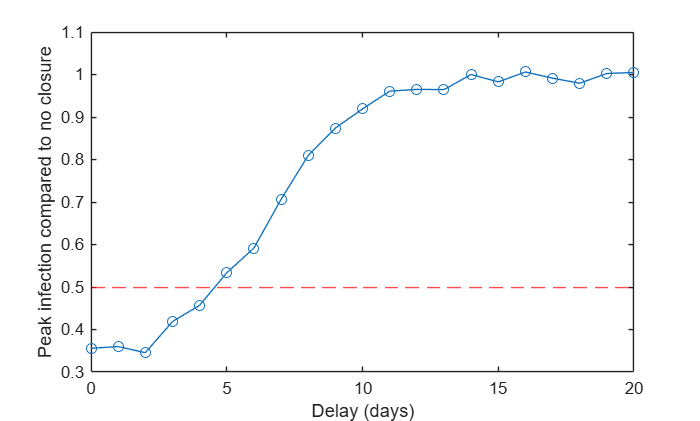

figure
plot(delays(1:end-1), ratio(1:end-1), '-o')
hold on
yline(0.5, '--r')
xlabel('Delay (days)')
ylabel('Peak infection compared to no closure')

*Fig. 4. Same as Fig. 2.*

*(Run simulations using your model, and make claims about the natural world based on those results. Connect each assumption to a limitation about what you *cannot* conclude based on your model.)*

*(You will likely need to write 2-3 code sections for this section [generating results with your model], and 2-3 paragraphs making claims using your results, and discussing the limitations.)*

*Suggested template: **FOR INSPIRATION, NOT TO USE DIRECTLY**.*

*A: remember this assumption from Section 4*

*B: but [our model still captures X important trend OR our question is about Y specifically OR our results are still informative because of Z]*

*T: so, we can conclude X, keeping in mind Y caveats*

We made the following assumptions to keep our model simple:

- All countries are the same size

- Connections are random and fixed over time, except at border closure

- Everyone starts susceptible except one agent in country 1

- Recovery gives permanent immunity

- No external births, deaths, or other changes to population

- No deaths due to disease

- Detection is instant and perfect 

- Closure is perfect and instant; at delay time it removes every between-country link, and all countries close together

Because of these assumptions, we also have the following limitations when using our model:

- We cannot model countries of different sizes

- We cannot model connections that change over time, unrelated to border closures

- We cannot model a disease that may begin with multiple people infected

- We cannot model reinfections

- We cannot model changes in population unrelated to the disease

- We cannot model changes in population related to the disease

- We cannot model false positives or negatives when detecting disease

- We cannot model imperfect closures; i.e. closures where there is still contact between countries

**todo things to justify:**

- **why we are allowed to not include the information we didn't include**

- **why we can simplify social dynamics this way**

## 7. Conclusion

We ask how fast countries need to close their borders after transmission is detected to reduce the spread of disease, which we defined as halving the peak number of infected. Studies show that closing borders helps and that earlier closure is better (Poirier et al., 2023), but none gave a time limit. Our model of four connected countries found that closure must happen within 2 days of detection to halve, and the time shrinks as the disease becomes more infectious. For a fast-spreading disease, a border closure only works if it happens almost immediately after the first cross-border case is detected. This is true for our model, and real detection delays and leaky borders would likely make the window shorter.

## 8. Future Work

We assume detection is instant, but the natural world has  delays and false negatives. A future model could add delay between infection and detection, and see how much it shortens the time available to close borders.

We assume closure removes every cross-border link. In reality, trade, essential travel, and illegal crossings continue. A future model could keep a fraction of between-country links after closing, and find how leaky a closure can be before it stops working.

We assume four equal countries with random connections. In real life countries differ in size and some are much more connected to others. A future model could use different pod sizes, or have different countries with more links and see whether the delay depends on who is infected first.

## References

*(List all references alphabetically by last name. Use the following format: Last name 1, Last name 2, ... (Year) "Title of Reference")*